# Machine Learning Verification of Primate Eye Tracker

## Load

### 4 Variables Files, Where T1 is data throughout the manuscript. T2-T3 are additional tests under different different animals.

load T1_Processed_Capcoil.mat
load T2_Processed_Smooth_Capcoil.mat
load T3_Processed_Smooth_Saccade_Capcoil.mat
rng(10)

Samprate_T2 = 29.4

Samprate_T2 = 29.4000

Samprate_T3 = 27.8

Samprate_T3 = 27.8000

### Horizontal Smooth

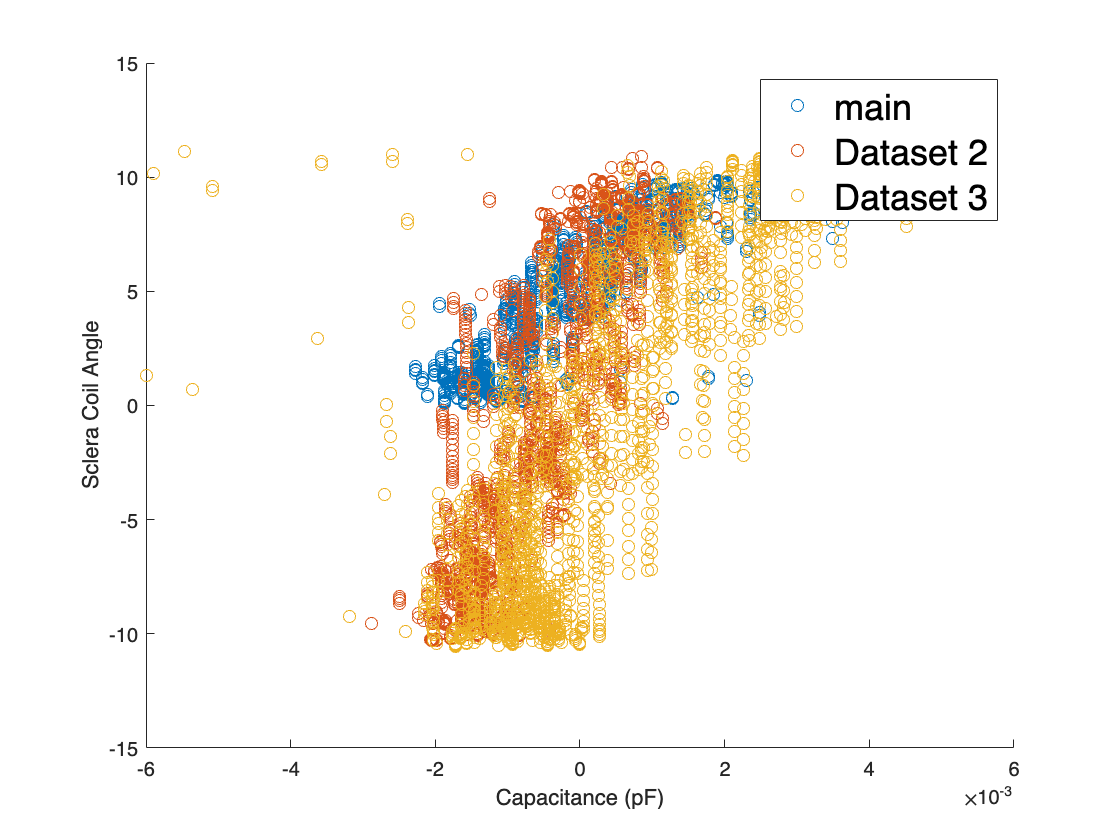

scatter(T1_Processed_HSMO_CAPCOIL(:,1),T1_Processed_HSMO_CAPCOIL(:,2)); hold on
scatter(T2_Processed_HSM_CAPCOIL(:,1),T2_Processed_HSM_CAPCOIL(:,2)); hold on
scatter(T3_Processed_HSM1_CAPCOIL(:,1),T3_Processed_HSM1_CAPCOIL(:,2)); hold off

xlabel("Capacitance (pF)"); xlim([-0.006 0.006])
ylabel("Sclera Coil Angle"); ylim([-15 15])
legend("main","Dataset 2", "Dataset 3",fontsize = 18)

### Trim to range

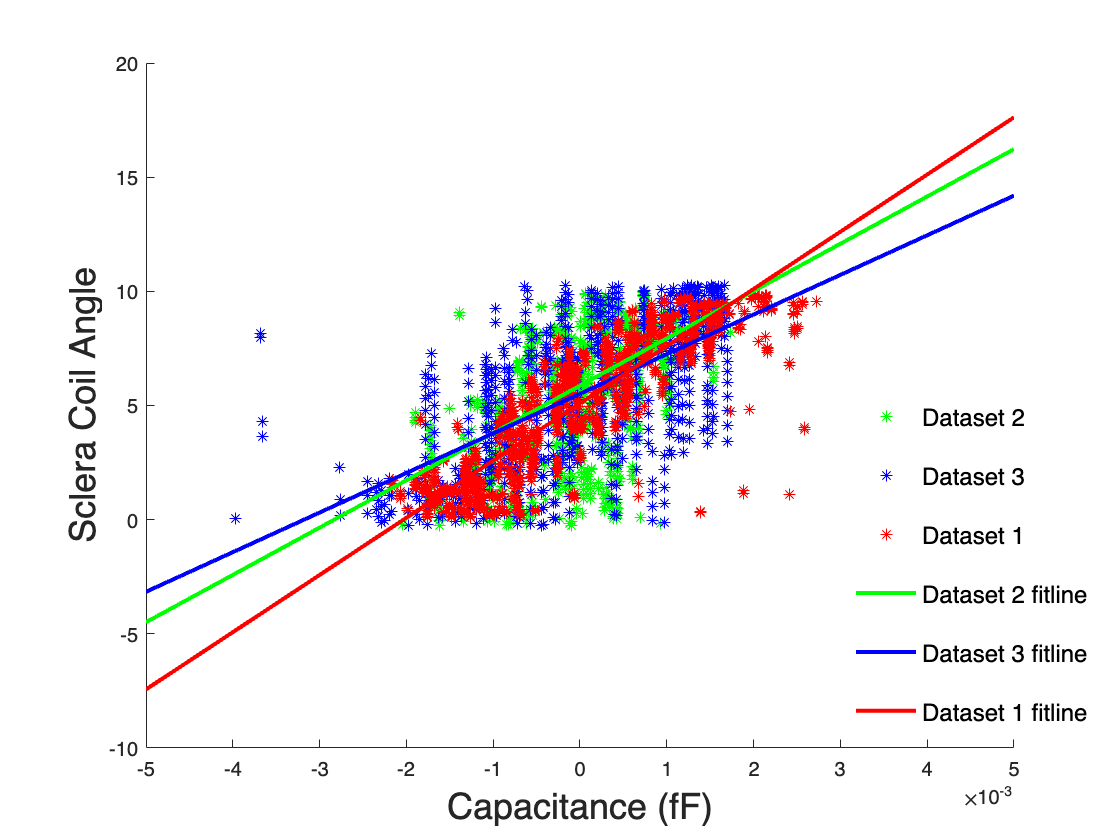

hsm1 = limitData(T1_Processed_HSMO_CAPCOIL, -0.3, 10.3, -3e-3, 3e-3);
hsm2 = limitData(T2_Processed_HSM_CAPCOIL, -0.3, 10.3, -3e-3, 3e-3);
hsm3 = limitData(T3_Processed_HSM1_CAPCOIL, -0.3, 10.3, -3e-3, 3e-3);

% fitline1 = polyfit(hsm1(:,1),hsm1(:,2),1);
% fitline2 = polyfit(hsm2(:,1),hsm2(:,2),1);
% fitline3 = polyfit(hsm3(:,1),hsm3(:,2),1);

fitline1 = flip(robustfit(hsm1(:,1),hsm1(:,2)));
fitline2 = flip(robustfit(hsm2(:,1),hsm2(:,2)));
fitline3 = flip(robustfit(hsm3(:,1),hsm3(:,2)));

scatter(hsm2(:,1),hsm2(:,2),"g*"); hold on
scatter(hsm3(:,1),hsm3(:,2),"b*"); hold on
scatter(hsm1(:,1),hsm1(:,2),"r*"); hold on; 

fplot(@(x) fitline2(1)*x+fitline2(2),"g", LineWidth=2); hold on;
fplot(@(x) fitline3(1)*x+fitline3(2),"b", LineWidth=2); hold on;
fplot(@(x) fitline1(1)*x+fitline1(2),"r", LineWidth=2); hold off;

legend("Dataset 2", "Dataset 3","Dataset 1","Dataset 2 fitline",...
    "Dataset 3 fitline","Dataset 1 fitline",'box','off', fontsize = 12)
legend("Position", [0.72002,0.11098,0.29643,0.4369])
xlabel("Capacitance (fF)",fontsize = 18); 
ylabel("Sclera Coil Angle",fontsize = 18); xlim([-5e-3 5e-3])

[train1, test1] = partitionArray(hsm1,0.2);
[train2, test2] = partitionArray(hsm2,0.2);
[train3, test3] = partitionArray(hsm3,0.2);


train12 = [train1; train2]; tes12 = [test1; test2];
train13 = [train1; train3]; tes13 = [test1; test3];
train23 = [train2; train3]; tes23 = [test2; test3];
trainAll = [train1; train2; train3];testAll = [test1; test2; test3];

trainVal = train3;
testVal = test3;
[maeTree, maeLinear, maeSVR, maeNN, runningTime] = computeP50MAE(trainVal, testVal)

maeTree = 1.0767

maeLinear = 2.0713

maeSVR = 1.8565

maeNN = 1.7247

runningTime =     0.2433    0.0861    0.0783    3.9607


rng(10);
trainVal = trainAll;
[treeModel,~] = trainTree(trainVal);

testVal = test2;
gazePredictTree = treeModel.predictFcn(testVal(:,1));
maeTree = median(abs(gazePredictTree - testVal(:,2)))

maeTree = 0.6827

### Vertical Smooth

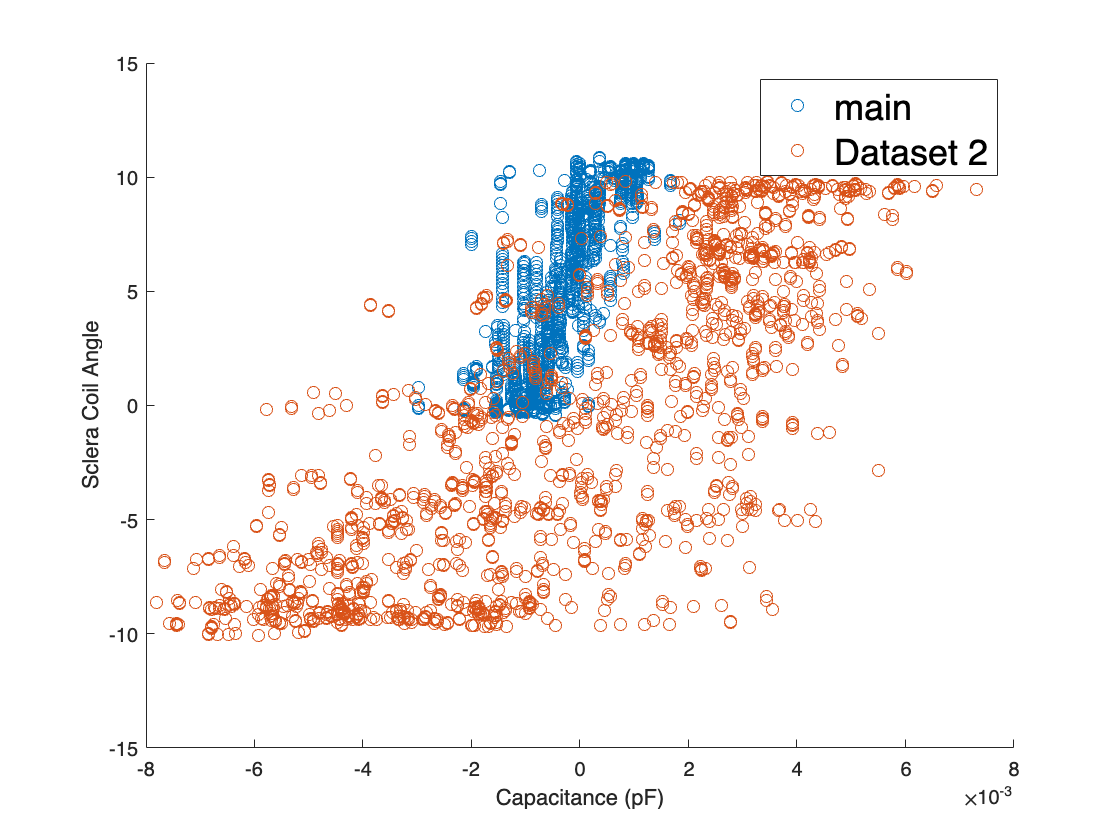

scatter(T1_Processed_VSMO_CAPCOIL(:,1),T1_Processed_VSMO_CAPCOIL(:,2)); hold on
scatter(T2_Processed_VSM_CAPCOIL(:,1),T2_Processed_VSM_CAPCOIL(:,2)); hold off

xlabel("Capacitance (pF)"); xlim([-0.008 0.008])
ylabel("Sclera Coil Angle"); ylim([-15 15])
legend("main","Dataset 2",fontsize = 18)

### Trim to range

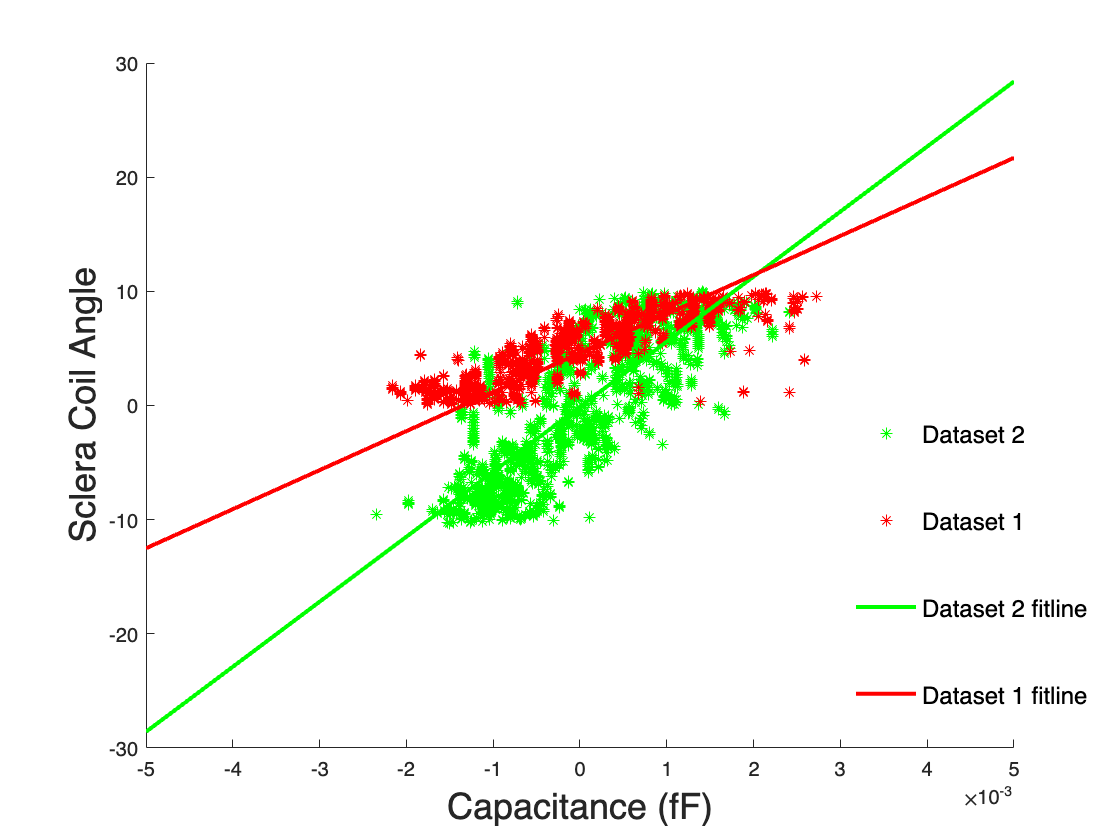

vsm1 = limitData(T1_Processed_VSMO_CAPCOIL, -10.3, 10.3, -6e-3, 6e-3);
vsm2 = limitData(T2_Processed_HSM_CAPCOIL, -10.3, 10.3, -6e-3, 6e-3);

fitline1 = polyfit(vsm1(:,1),vsm1(:,2),1);
fitline2 = polyfit(vsm2(:,1),vsm2(:,2),1);

scatter(vsm2(:,1),vsm2(:,2),"g*"); hold on
scatter(hsm1(:,1),hsm1(:,2),"r*"); hold on; 

fplot(@(x) fitline2(1)*x+fitline2(2),"g", LineWidth=2); hold on;
fplot(@(x) fitline1(1)*x+fitline1(2),"r", LineWidth=2); hold off;

legend("Dataset 2", "Dataset 1","Dataset 2 fitline",...
    "Dataset 1 fitline",'box','off', fontsize = 12)
legend("Position", [0.72002,0.11098,0.29643,0.4369])
xlabel("Capacitance (fF)",fontsize = 18); 
ylabel("Sclera Coil Angle",fontsize = 18); xlim([-5e-3 5e-3])

[trainv1, testv1] = partitionArray(vsm1,0.2);
[trainv2, testv2] = partitionArray(vsm2,0.2);
trainVal = trainv1;
testVal = testv1;
[maeTree, maeLinear, maeSVR, maeNN, runningTime] = computeP50MAE(trainVal, testVal)

maeTree = 0.4894

maeLinear = 1.7224

maeSVR = 0.9436

maeNN = 1.2201

runningTime =     0.2298    0.0821    0.0991    5.7940


### Horizontal Saccade

scatter(T1_Processed_HSAC_CAPCOIL(:,1),T1_Processed_HSAC_CAPCOIL(:,2)); hold on
scatter(T3_Processed_HSAC1_CAPCOIL(:,1),T3_Processed_HSAC1_CAPCOIL(:,2)); hold off

xlabel("Capacitance (pF)"); xlim([-0.006 0.006])
ylabel("Sclera Coil Angle"); ylim([-15 15])
legend("main","Dataset 2", "Dataset 3",fontsize = 18)

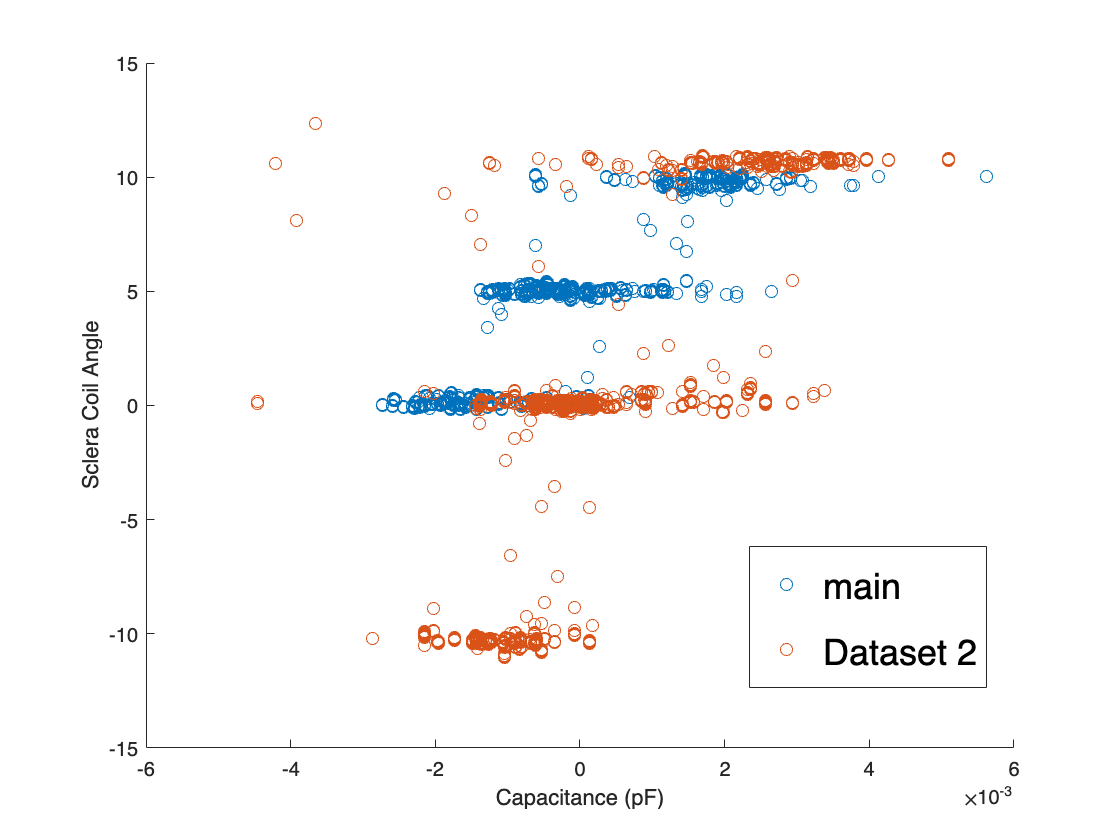

legend("Position", [0.66862,0.18084,0.2125,0.16905])

### Trim to range

hsac1 = limitData(T1_Processed_HSAC_CAPCOIL, -0.3, 13.3, -3e-3, 6e-3);
hsac2 = limitData(T3_Processed_HSAC1_CAPCOIL, -0.3, 13.3, -3e-3, 6e-3);

fitline1 = polyfit(hsac1(:,1),hsac1(:,2),1);
fitline2 = polyfit(hsac2(:,1),hsac2(:,2),1);

scatter(hsac2(:,1),hsac2(:,2),"g*"); hold on
scatter(hsac1(:,1),hsac1(:,2),"r*"); hold on; 

fplot(@(x) fitline2(1)*x+fitline2(2),"g", LineWidth=2); hold on;
fplot(@(x) fitline1(1)*x+fitline1(2),"r", LineWidth=2); hold off;

legend("Dataset 2", "Dataset 3","main","Dataset 2 fitline",...
    "Dataset 3 fitline","main fitline",'box','off', fontsize = 12)

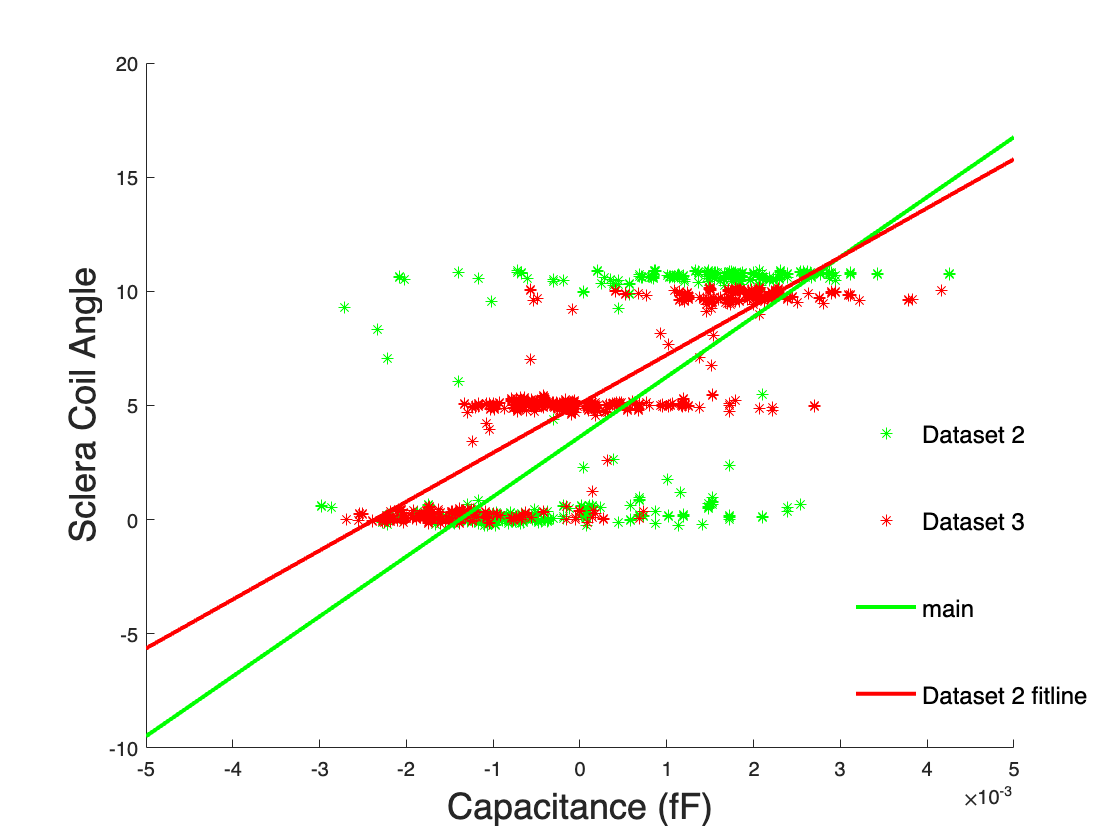

legend("Position", [0.72002,0.11098,0.29643,0.4369])
xlabel("Capacitance (fF)",fontsize = 18); 
ylabel("Sclera Coil Angle",fontsize = 18); xlim([-5e-3 5e-3])

[trainc1, testc1] = partitionArray(hsac1,0.2);
[trainc2, testc2] = partitionArray(hsac2,0.2);

trainVal = trainc1;
testVal = testc1;
[maeTree, maeLinear, maeSVR, maeNN, runningTime] = computeP50MAE(trainVal, testVal)

maeTree = 0.0544

maeLinear = 1.0189

maeSVR = 0.3438

maeNN = 0.2139

runningTime =     0.2618    0.0858    0.0954    7.1796


### Horizontal Fixation, Horizontal Smooth 0.5 hz, Vertical Saccade, Vertical Smooth 0.2hz (only in Data set 1)

hfix = T1_Processed_HFIX_CAPCOIL;
hsmo_5 = T1_Processed_HSMO_05_CAPCOIL;
vsac = T1_Processed_VSAC_CAPCOIL;
vsmo = T1_Processed_VSMO_CAPCOIL;
vsmo_0_2 = T1_Processed_VSMO_02_CAPCOIL;

[train_hfix, test_hfix] = partitionArray(hfix,0.2);
[train_hsmo5, test_hsmo5] = partitionArray(hsmo_5,0.2);
[train_vsac, test_vsac] = partitionArray(vsac,0.2);
[train_vsmo, test_vsmo] = partitionArray(vsmo,0.2);
[train_vsmo_0_2, test_vsmo_0_2] = partitionArray(vsmo_0_2,0.2);

trainVal = train_vsac;
testVal = test_vsac;
[maeTree, maeLinear, maeSVR, maeNN, runningTime] = computeP50MAE(trainVal, testVal)

maeTree = 0.0727

maeLinear = 1.5862

maeSVR = 0.3909

maeNN = 1.0998

runningTime =     0.2379    0.0842    0.1007    6.5866


function dataout = limitData(datain, angle_low, angle_high, cap_low, cap_high)
    angleMask = (datain(:, 2) >= angle_low) & (datain(:, 2) <= angle_high);
    capMask = (datain(:, 1) >= cap_low) & (datain(:, 1) <= cap_high);
    dataout = datain(angleMask & capMask, :);
    dataout(:,1) = detrend(dataout(:,1),0); % Remove 0-th order constant bias
end

function [Training, Testing] = partitionArray(inArray, fraction)
    rng(10);
    if (fraction < 0.01 || fraction > 0.99)
        fraction = 0.2; disp("Illegal fraction. Reset to 0.2.");
    end
    inArray = inArray(randperm(size(inArray,1)),:);
    c = cvpartition(size(inArray,1),'Holdout',fraction);
    Train_Index = training(c);
    Test_Index = test(c);
    Training = inArray(Train_Index,:);
    Testing = inArray(Test_Index,:);
end

function [maeTree, maeLinear, maeSVR, maeNN, timeEach] = computeP50MAE(trainVal, testVal)
    timeEach = [0 0 0 0];
    rng(10);
    
    tic;
    [treeModel,~] = trainTree(trainVal);
    gazePredictTree = treeModel.predictFcn(testVal(:,1));
    maeTree = median(abs(gazePredictTree - testVal(:,2)));
    timeEach(1) = toc;
    
    tic;
    [linearModel,~] = trainLinear(trainVal);
    gazePredictLinear = linearModel.predictFcn(testVal(:,1));
    maeLinear = median(abs(gazePredictLinear - testVal(:,2)));
    timeEach(2) = toc;
    
    tic;
    [svmModel,~] = trainSVR(trainVal);
    gazePredictSVR = svmModel.predictFcn(testVal(:,1));
    maeSVR = median(abs(gazePredictSVR - testVal(:,2)));
    timeEach(3) = toc;

    tic;
    [NNModel,~] = trainNN(trainVal);
    gazePredictNN = NNModel.predictFcn(testVal(:,1));
    maeNN = median(abs(gazePredictNN - testVal(:,2)));
    timeEach(4) = toc;
end